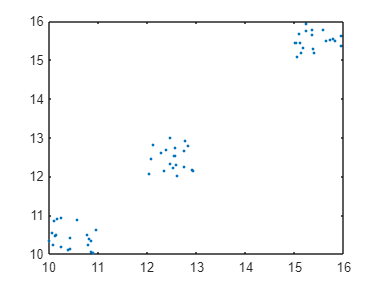

x = [rand(20,2)+12; rand(20,2)+10; rand(20,2)+15];
figure(1)
plot(x(:,1),x(:,2),'.')

clusterer = clusterDBSCAN('Epsilon',1,'MinNumPoints',3);
idxEpsilon1 = clusterer(x);
clusterer.Epsilon = 3;
idxEpsilon2 = clusterer(x);
clusterer.Epsilon = 5;
idxEpsilon5 = clusterer(x);
clusterer.Epsilon = 10;
idxEpsilon10 = clusterer(x);

hAx1 = subplot(1,1,1);

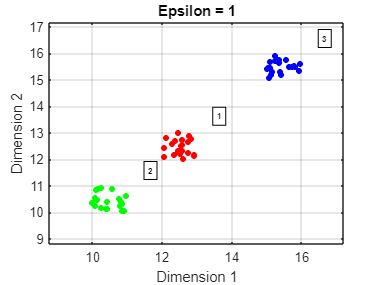

plot(clusterer,x,idxEpsilon1, ...
    'Parent',hAx1,'Title','Epsilon = 1')
hAx2 = subplot(1,1,1);

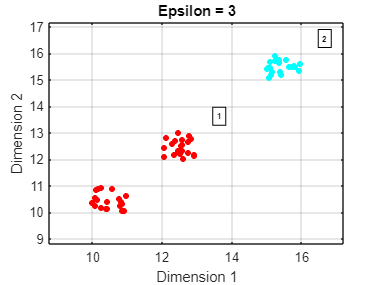

plot(clusterer,x,idxEpsilon2, ...
    'Parent',hAx2,'Title','Epsilon = 3')
hAx3 = subplot(1,1,1);

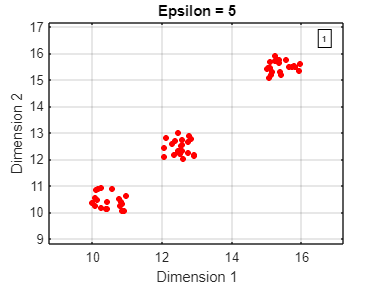

plot(clusterer,x,idxEpsilon5, ...
    'Parent',hAx3,'Title','Epsilon = 5')
hAx4 = subplot(1,1,1);

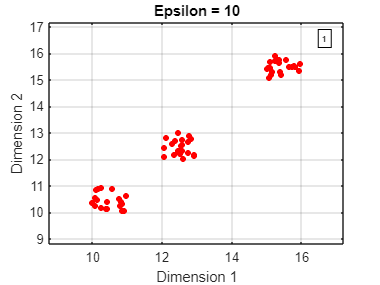

plot(clusterer,x,idxEpsilon10, ...
    'Parent',hAx4,'Title','Epsilon = 10')